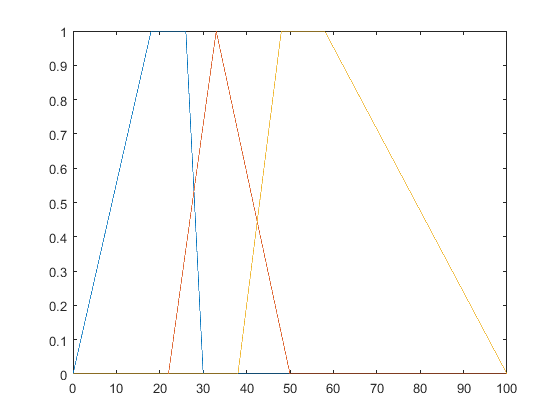

clc;
clear;

global X mu_X  mu_xi;
altsinir_yas=0; ustsinir_yas=100;
altsinir_bmi=0; ustsinir_bmi=45;
altsinir_semptom=0; ustsinir_semptom=100;
 
tedavi_altsinir=0; tedavi_ustsinir=1;

sgn=[0.15 0.55 0.85];
 
%numerik girisler
yas_xi=40; bmi_xi=24.7; semptom_xi=60;

%Numerik girislerin, girsi cikis uyelk fonk ,Bulanik kumelerin tanimlanmaasi
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%1. Yash girisine ait uyelik fonksiyonlari ve bulaniklashtirma
%Uyelik derecelerinin tanimlanmasi
trapezoid(altsinir_yas,0,18,26,30,ustsinir_yas,yas_xi); x_genc=X; genc_xi=mu_xi; mu_genc=mu_X;
hold on;
triangle(altsinir_yas,22,33,50,ustsinir_yas,yas_xi); x_orta=X; orta_xi=mu_xi; mu_orta=mu_X;

trapezoid(altsinir_yas,38,48,58,100, ustsinir_yas,yas_xi); x_yasli=X; yasli_xi=mu_xi; mu_yasli=mu_X;
    hold off;

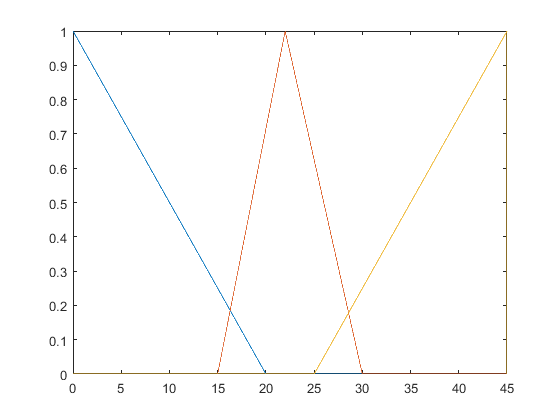


%2. Vucut kutle indeksine ait uyelik fonk girisleri...
triangle(altsinir_bmi,0,0,20,ustsinir_bmi, bmi_xi);  bmi_dusuk_xi=mu_xi; 
hold on;
triangle(altsinir_bmi,15,22,30,ustsinir_bmi, bmi_xi);  bmi_orta_xi=mu_xi; 
triangle(altsinir_bmi,25,45,45,ustsinir_bmi, bmi_xi); bmi_yuksek_xi=mu_xi; 
hold off;

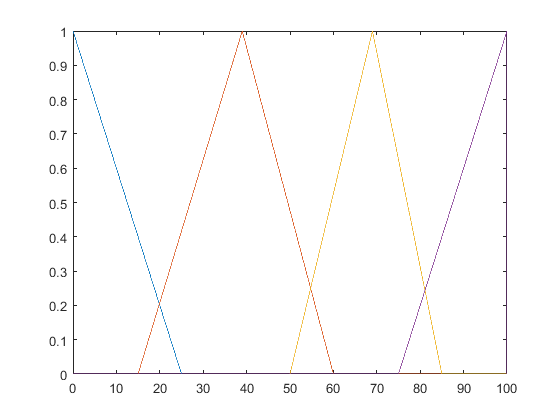


%3. Semptomlara ait uyelik fonk girisleri ...
triangle(altsinir_semptom,0,0,25,ustsinir_semptom,semptom_xi);  semptom_az_xi=mu_xi; 
hold on;
triangle(altsinir_semptom,15,39,60,ustsinir_semptom,semptom_xi);  semptom_orta_xi=mu_xi; 
triangle(altsinir_semptom,50,69,85,ustsinir_semptom,semptom_xi);  semptom_yuksek_xi=mu_xi; 
triangle(altsinir_semptom,75,100,100,ustsinir_semptom,semptom_xi);  semptom_cokyuksek_xi=mu_xi;
hold off;


%cikish Tedavi
t1=sgn(1)*yas_xi+sgn(1)*bmi_xi+sgn(1)*semptom_xi+sgn(1);%dinlenme
t2=sgn(2)*yas_xi+sgn(2)*bmi_xi+sgn(2)*semptom_xi+sgn(2); %ilaclar
t3=sgn(3)*yas_xi+sgn(3)*bmi_xi+sgn(3)*semptom_xi+sgn(3); %ameliyat

%Kurallar
w1=min(min(genc_xi, bmi_yuksek_xi), semptom_cokyuksek_xi);
w2=min(min(orta_xi,bmi_yuksek_xi),semptom_cokyuksek_xi);
w3=min(min(yasli_xi,bmi_orta_xi),semptom_cokyuksek_xi);
w4=min(min(yasli_xi,bmi_yuksek_xi),semptom_cokyuksek_xi);
w5=min(min(genc_xi,bmi_yuksek_xi),semptom_yuksek_xi);
w6=min(min(orta_xi,bmi_orta_xi),semptom_yuksek_xi);
w7=min(min(genc_xi,bmi_yuksek_xi),semptom_az_xi);
w8=min(min(genc_xi,bmi_dusuk_xi),semptom_orta_xi);
w9=min(min(orta_xi,bmi_dusuk_xi),semptom_orta_xi);

SAT = t1*w1+t1*w8+t2*w5+t2*w6+t2*w7+t3*w2+t3*w3+t3*w4+t3*w9;


toplam_agirlik = w1  + w2 + w3 + w4 +w5+w6+w7+w8+w9;
if toplam_agirlik == 0
    'Deneme'
end
z = SAT/toplam_agirlik

z = 69.1350